clearvars

folder = "../physionet.org/textdata/";
file = "3600293_0004.txt";

data = cell2mat(textscan( fopen([folder+file]), '%f %f %f', 'TreatAsEmpty', '-', 'EmptyValue', 0));


rng = 116000:119000;
time = data(rng,1);
ppg = data(rng,3);
abp = data(rng,2);

segmentedPPG = segmentSignal(ppg,5);

    24




segmentedABP = segmentSignal(abp,5);

    25



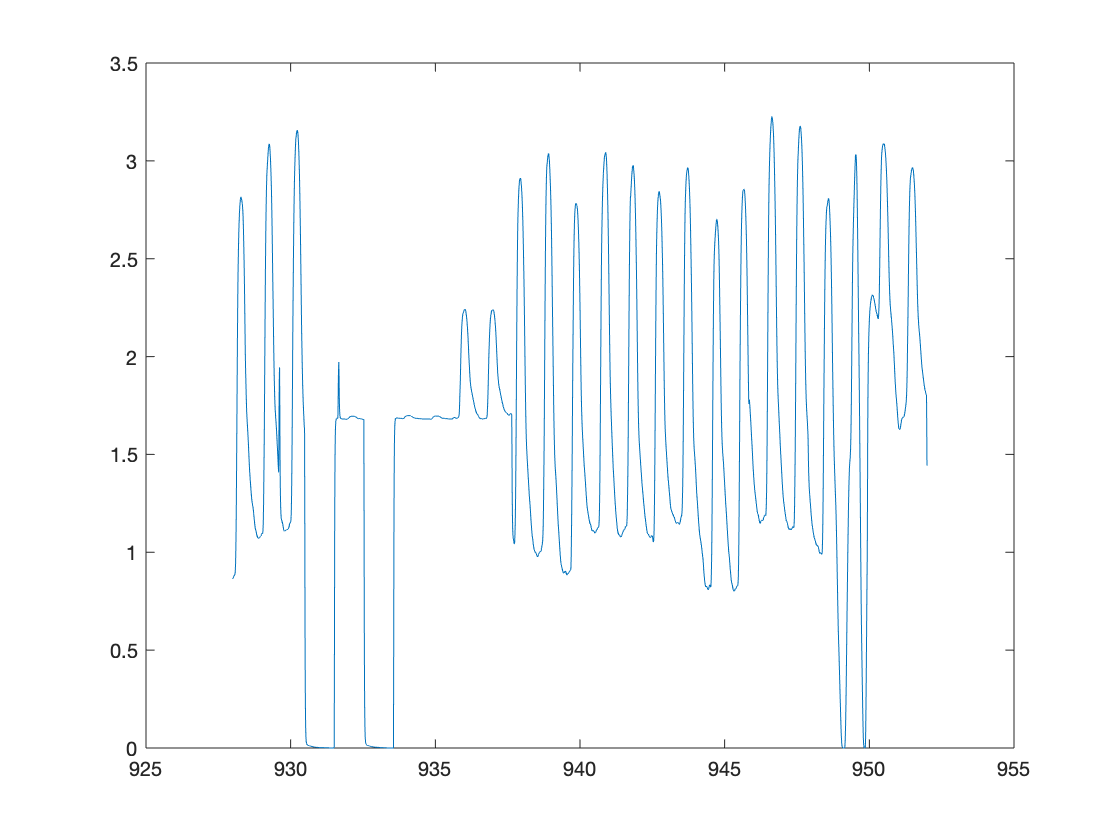



plot(time, ppg);
hold on
%plot(time, abp);
hold off

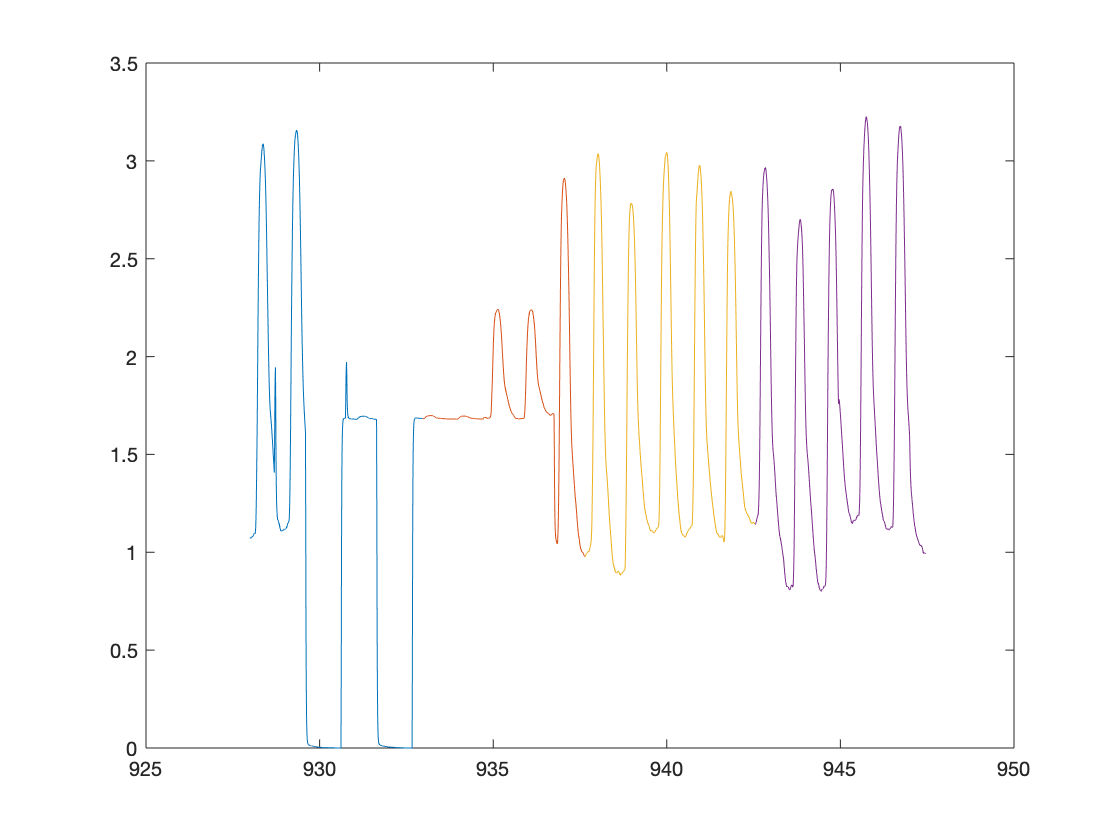


t_id = 1;
for i = 1:length(segmentedPPG)
    plot(time(t_id:t_id+length(segmentedPPG{i})-1), segmentedPPG{i});
    hold on;
    t_id = t_id+length(segmentedPPG{i});
end

hold off

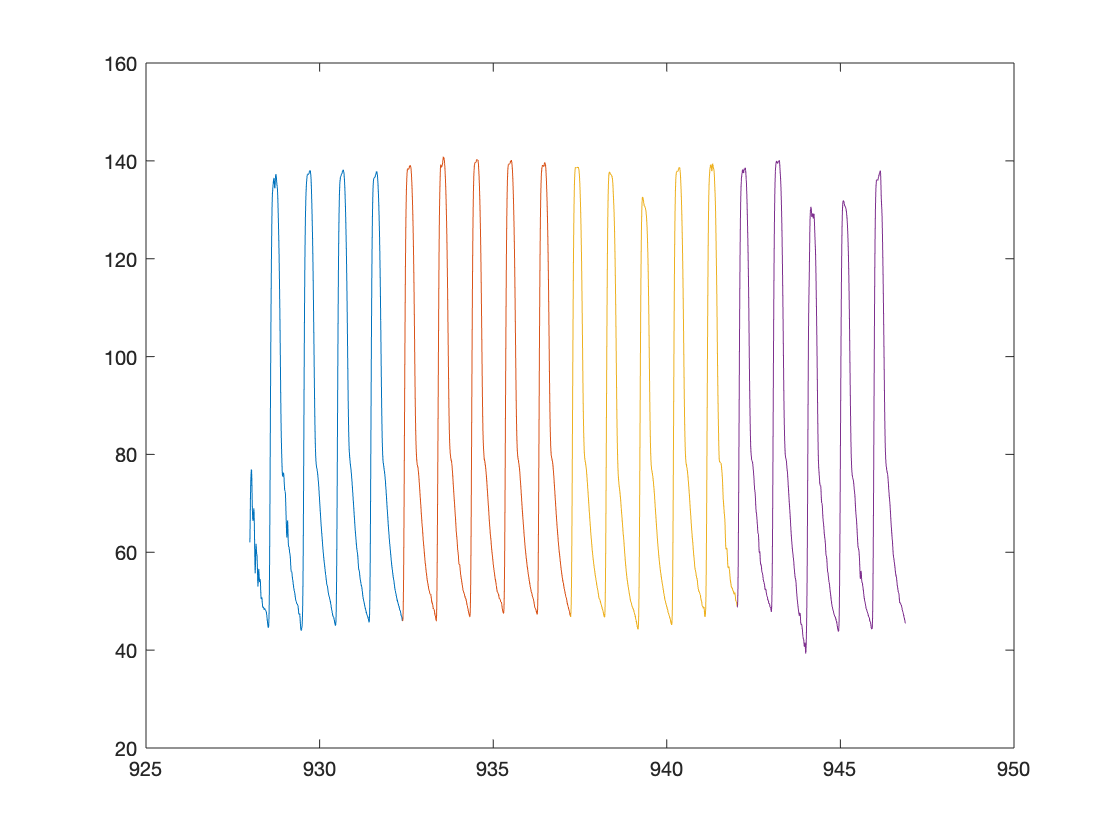


t_id = 1;
for i = 1:length(segmentedABP)
    plot(time(t_id:t_id+length(segmentedABP{i})-1), segmentedABP{i});
    hold on;
    t_id = t_id+length(segmentedABP{i});
end
hold off